% MATLAB script to read in Excel time series data, process it, 
% and plot the log-transformed values.

% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
data = readtable('Daily_Loggers_only_Sum.csv');

% Check if date format is correct (assumes date is in the first column)
dates = data{:, 1}; % Extract dates
dates = datetime(dates, 'InputFormat', 'yyyy-MM-dd'); % Adjust date format if needed

% Check if date format is correct (assumes date is in the first column)
dates = data{:, 1}; % Extract dates
dates = datetime(dates, 'InputFormat', 'yyyy-MM-dd'); % Adjust date format if needed

% Check for any NaN or null values in the logger data columns (2 to 21)
loggers_data = data{:, 2:21};  % Extract the logger data (columns 2 to 21)

% Handle missing data (NaN values) by interpolation (linear)
loggers_data = fillmissing(loggers_data, 'linear');  % Linear interpolation for missing values

% Check minimum values of the data before applying log transformation
min_values = min(loggers_data);
disp('Minimum values in the data before log transformation:');

Minimum values in the data before log transformation:


disp(min_values);

  Columns 1 through 14

           8         194         765           1           3          85         284          18           0         473         535          87         523        2621

  Columns 15 through 20

       20702          17           5          24           0        2204



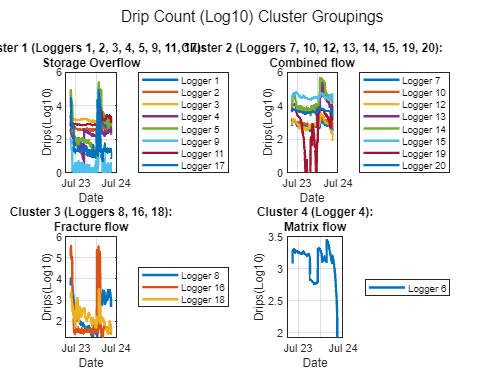


% Apply log10 transformation to the logger data (ensure it's positive before log transformation)
% Shift values to avoid log of zero and to prevent negative values
loggers_data(loggers_data <= 0) = 1;  % Replace values <= 0 with 1 to avoid log(0)
loggers_data = log10(loggers_data);   % Now apply log10

% Define clusters for plotting (using column indices, not 1-based logger numbers)
clusters = {
    [1, 2, 3, 4, 5, 9, 11, 17],    % Cluster 1: Logger 1 (col 2), Logger 2 (col 3), etc.
    [7, 10, 12, 13, 14, 15, 19, 20], % Cluster 2
    [8, 16, 18],               % Cluster 3
    6                        % Cluster 4
};

% Define unique names for each subplot (clusters)
% subplot_titles = {
%     'Cluster 1 (Loggers 1, 2, 3, 4, 5, 9, 11, 17): Storage Overflow' % Title for Cluster 1
%     'Cluster 2 (Loggers 7, 10, 12, 13, 14, 15, 19, 20): Combined flow' % Title for Cluster 2
%     'Cluster 3 (Loggers 8, 16, 18): Fracture flow'  % Title for Cluster 3
%     'Cluster 4 (Logger 4): Matrix flow'  % Title for Cluster 4
% };

% Define unique names for each subplot with line breaks
subplot_titles = {
    sprintf('Cluster 1 (Loggers 1, 2, 3, 4, 5, 9, 11, 17):\nStorage Overflow'), % Title for Cluster 1
    sprintf('Cluster 2 (Loggers 7, 10, 12, 13, 14, 15, 19, 20):\nCombined flow'), % Title for Cluster 2
    sprintf('Cluster 3 (Loggers 8, 16, 18):\nFracture flow'),  % Title for Cluster 3
    sprintf('Cluster 4 (Logger 4):\nMatrix flow')  % Title for Cluster 4
};


% Create a figure for plotting
figure;

% Loop through each cluster to create a separate plot for each
for i = 1:length(clusters)
    % Extract the current cluster's loggers (indices based on columns 2-21)
    cluster = clusters{i};  
    cluster_data = loggers_data(:, cluster);  % Extract data for the current cluster
    
    % Create a subplot for each cluster
    %subplot(4, 1, i);  % 2x2 grid of subplots, position i

    %AGU subplots
    subplot(2, 2, i);  % 2x2 grid of subplots, position i

    % Plot the data for the current cluster
    plot(dates, cluster_data, 'LineWidth', 2);
    
    % Add a legend for the current cluster (adjusted for correct column indices)
    legend_labels = cell(1, length(cluster));  % Pre-allocate a cell array for labels
    for j = 1:length(cluster)
        % Adjust for correct column numbers: Logger 1 is in column 2, Logger 2 is in column 3, etc.
        legend_labels{j} = ['Logger ' num2str(cluster(j))];
    end
    legend(legend_labels, 'Location', 'eastoutside');  % Add the legend to the subplot

    % Set the title and labels for the subplot
    % title(subplot_titles{i});  % Use the unique subplot title
    title(subplot_titles{i}, 'Interpreter', 'none'); % Apply title with line breaks
    xlabel('Date');
    ylabel('Drips(Log10)');
    grid on;
end

% Adjust the layout to make sure plots are properly spaced
sgtitle('Drip Count (Log10) Cluster Groupings');  % Overall title for the figure


% Save the figure
% saveas(f, 'Drip Count Cluster Groupings1.png');  % Saves the current figure
% exportgraphics(f, 'Drip Count Cluster Groupings2.png', 'Resolution', 1500);  % Save with 1500 DPI resolution

% (A) Storage baseflow group with curves displaying relatively similar trajectories. All curves are relatively flat compared to secondary groups. 
% (B) Fracture baseflow group. HW_16b is the red curve, HW_20b is the black curve and HW_21b is the green curve. (
% C) Overflow group 
% (D) COMBINED FLOW
